clc
clf
clear


nsol=5:10:15;
nPert=3:4:7;
To=75:50:125;
comb=zeros(8,3);
for i=1:2
    comb(4*(i-1)+1:4*i,1)=nsol(i)*ones(4,1);
    for j=1:4
        k=mod(j-1,2)+1;
        comb(2*(j-1)+1:2*j,2)=nPert(k)*ones(2,1);
    end
    for j=1:8
        k=mod(j-1,2)+1;
        comb(j,3)=To(k);
    end
end
comb=[10 4 100; comb];
names="nsol="+string(comb(:,1))+", per="+string(comb(:,2))+", T_{0}="+string(comb(:,3));
names=["Constructivo"
    "GRASP"
    "ACO"
    "VND"
    names];

GAP1=[36836.95
26654.93
9975.12
4035.29
11634.98
14044.01
10651.53
7810.85
8255.94
9300.52
13322.84
10138.62
11669.74
];
GAP2=[59.71
47.19
15.41
9.65
21.22
21.70
20.99
20.40
20.23
20.26
18.85
19.20
20.63
];
AvTh=[ 97.97 
 86.16 
 46.83 
 18.88 
 47.02 
 60.07 
 48.50 
 31.91 
 35.76 
 38.47 
 55.80 
 40.96 
 49.40 
];
MinTh=[  31.49 
 32.24 
 18.07 
 0.50 
 1.50 
 2.72 
 1.19 
 0.63 
 4.14 
 0.14 
 0.30 
 0.64 
 1.14 
];
time =[435.5603206
  5100.0980243
  5100.1409967
  5100.1104061
  5100.1206146
  5100.2267524
  5100.1299175
  5100.0575514
  5100.1010799
  5100.1399054];               

## Resultados

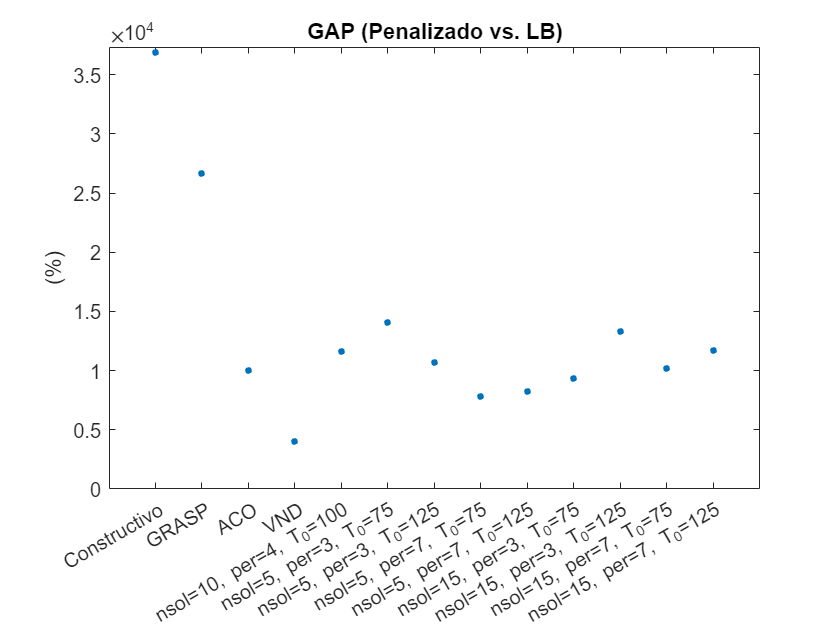

plot(GAP1,'.', 'markersize', 10)
xticks(1:13)
xticklabels(names)
xlim([0,14])
ylim([0 max(GAP1)+500])
title("GAP (Penalizado vs. LB)")
ylabel("(%)")

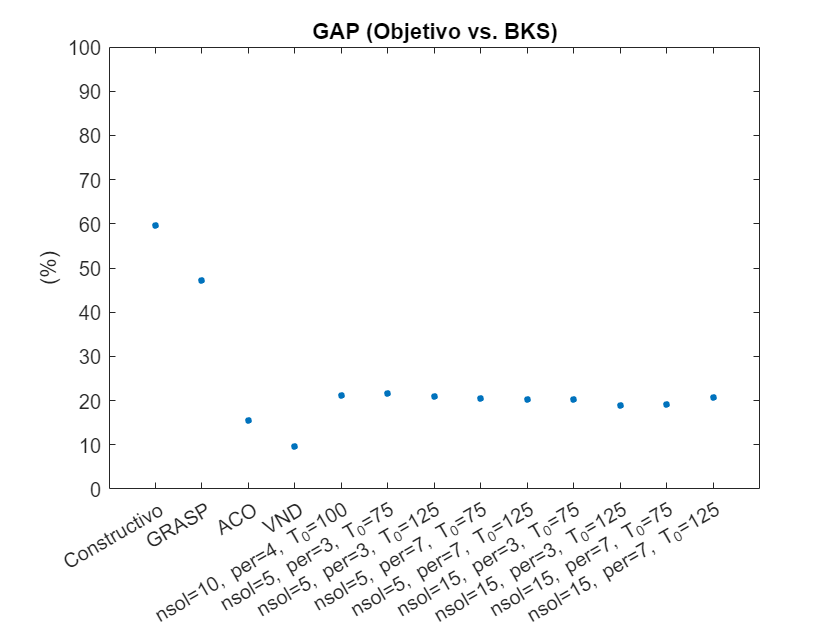

plot(GAP2,'.', 'markersize', 10)
xticks(1:13)
xticklabels(names)
xlim([0,14])
ylim([0 100])
title("GAP (Objetivo vs. BKS)")
ylabel("(%)")

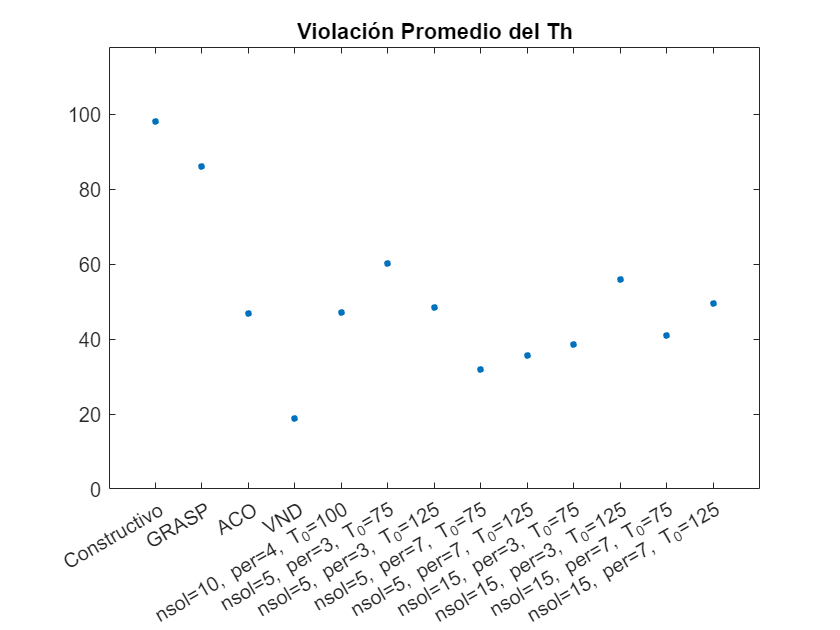


plot(AvTh,'.', 'markersize', 10)
xticks(1:13)
xticklabels(names)
xlim([0,14])
ylim([0 max(AvTh)+20])
title("Violación Promedio del Th")
ylabel("")

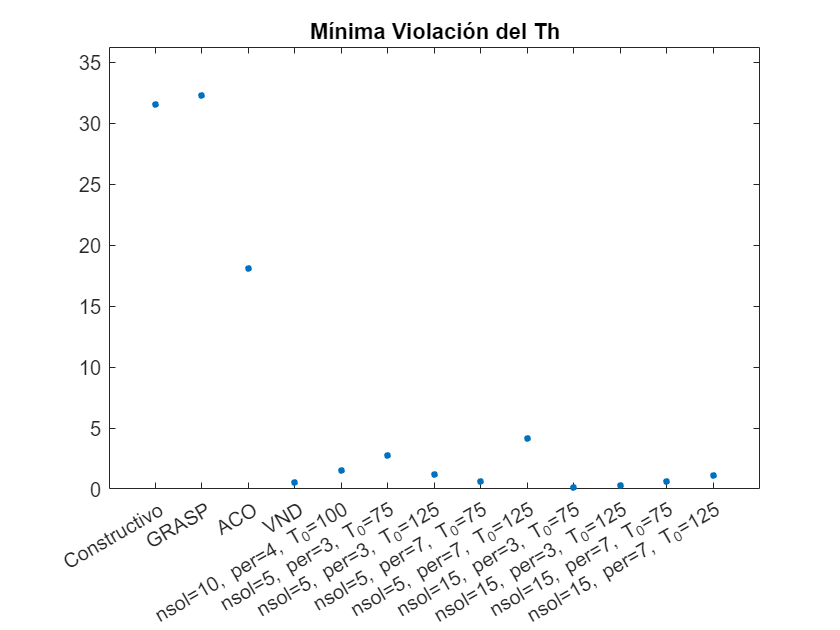


plot(MinTh,'.', 'markersize', 10)
xticks(1:13)
xticklabels(names)
xlim([0,14])
ylim([0 max(MinTh)+4])
title("Mínima Violación del Th")
ylabel("")

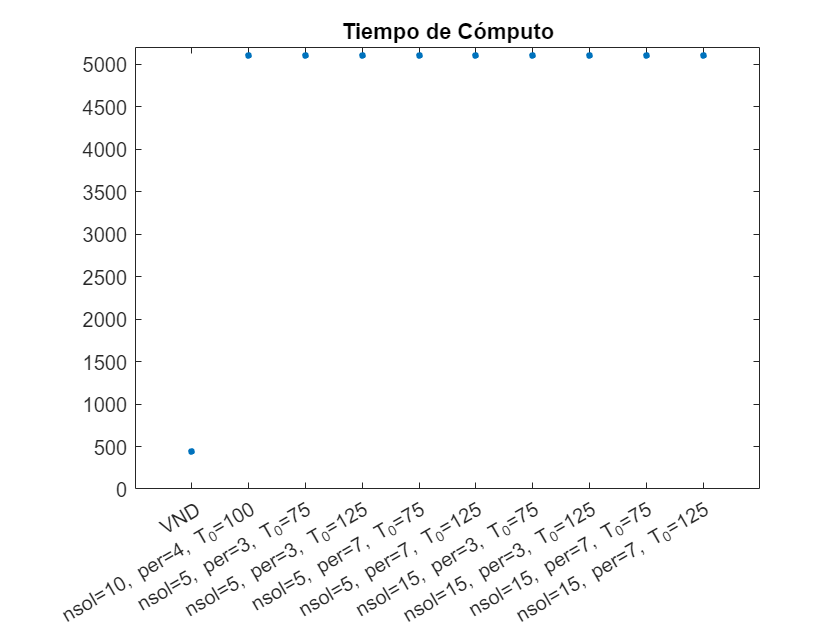

plot(time,'.', 'markersize', 10)
xticks(1:10)
xticklabels(names(4:end))
xlim([0,11])
ylim([0 max(time)+100])
title("Tiempo de Cómputo")
ylabel("")

GAP1T=[6488.58	271.93	371.13	985.11	134.51	6359.43	3919.36	12345.59 2503.36 8296.42 5311.55 1436.53
10877.57	3011.11	1137.46	489.26	716.53 4583.37	6470.35	26546.93 27607.63 10558.20 284.03 1447.76]';

GAP2T=[11.65	7.67	9.18	9.93	10.40	16.98	10.45	10.30	13.06	4.59	5.00	6.56
5.33	17.90	11.03	13.77	23.21	20.01	38.30	39.27	39.45	9.86	10.08	16.61]';

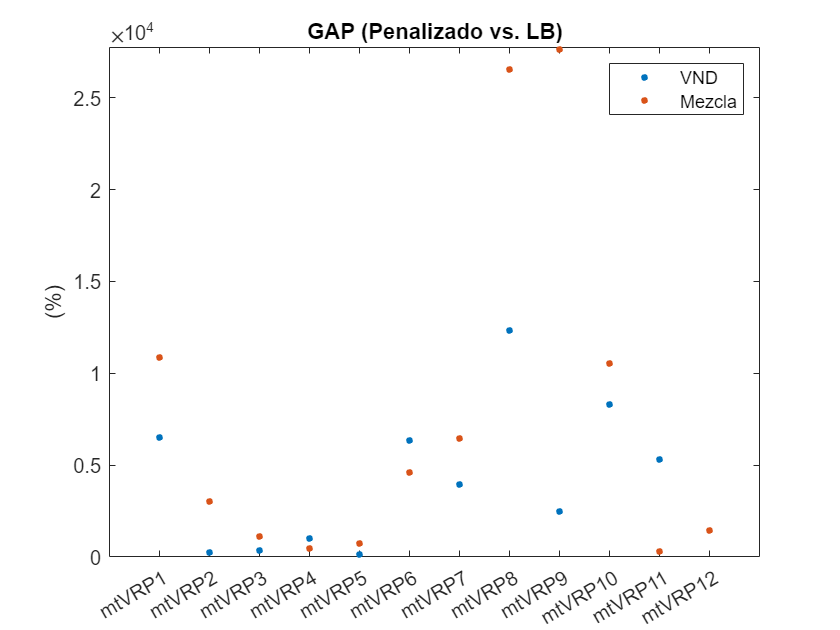


plot(GAP1T,'.', 'markersize', 10)
xticks(1:13)
xticklabels("mtVRP"+string(1:12))
xlim([0,13])
ylim([0 max(GAP1T,[],"all")+150])
title("GAP (Penalizado vs. LB)")
ylabel("(%)")
legend(["VND", "Mezcla"])

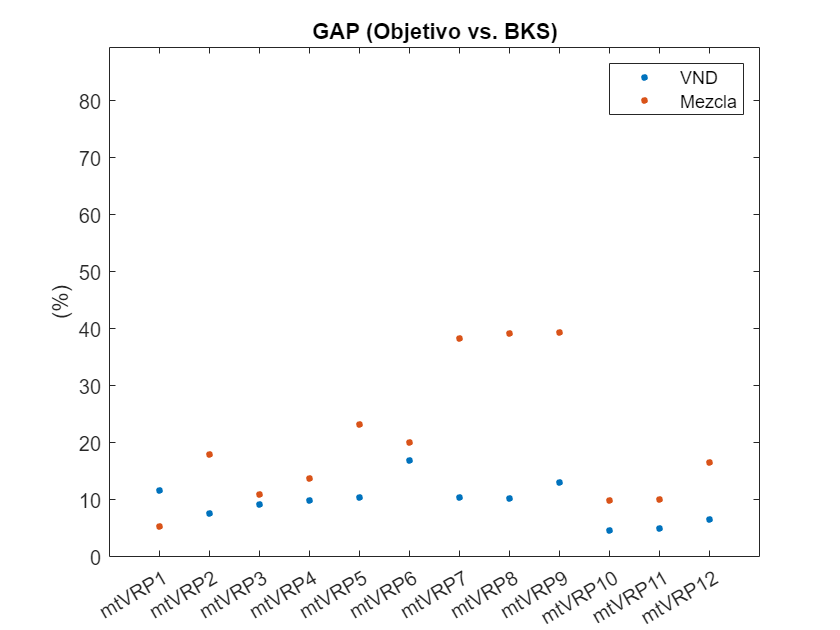


plot(GAP2T,'.', 'markersize', 10)
xticks(1:13)
xticklabels("mtVRP"+string(1:12))
xlim([0,13])
ylim([0 max(GAP2T,[],"all")+50])
title("GAP (Objetivo vs. BKS)")
ylabel("(%)")
legend(["VND", "Mezcla"])